opticalFlow = 'C:\Users\maran\MATLAB Drive\thesisFinal\testTrackResults\oCRopFlo.csv'

opticalFlow = 'C:\Users\maran\MATLAB Drive\thesisFinal\testTrackResults\oCRopFlo.csv'


M = csvread(opticalFlow)

M =          0         0
    0.2000    0.0252
    0.4000    0.0184
    0.6000    0.0089
    0.8000    0.0125
    1.0000    0.0183
    1.2000    0.0198
    1.4000    0.0210
    1.6000    0.0229
    1.8000    0.0246


x = M(:,1)

x =          0
    0.2000
    0.4000
    0.6000
    0.8000
    1.0000
    1.2000
    1.4000
    1.6000
    1.8000


y = M(:,2)

y =          0
    0.0252
    0.0184
    0.0089
    0.0125
    0.0183
    0.0198
    0.0210
    0.0229
    0.0246



sOne = rms(y(50:350,:))

sOne = 0.0440

sTwo = rms(y(400:500,:))

sTwo = 0.0485

%sThr = rms(y(245:285,:))
%sFour = rms(y(365:430,:))
sM = [sOne sTwo]

sM =     0.0440    0.0485



speed = string(round(rms([sOne sTwo]),3, 'significant'))

speed = "0.0463"

sD = num2str(std(sM),'%.2E')

sD = '3.22E-03'

speed = 'Average '  + speed +' '+ char(177) + ' ' + sD

speed = "Average 0.0463 ± 3.22E-03"

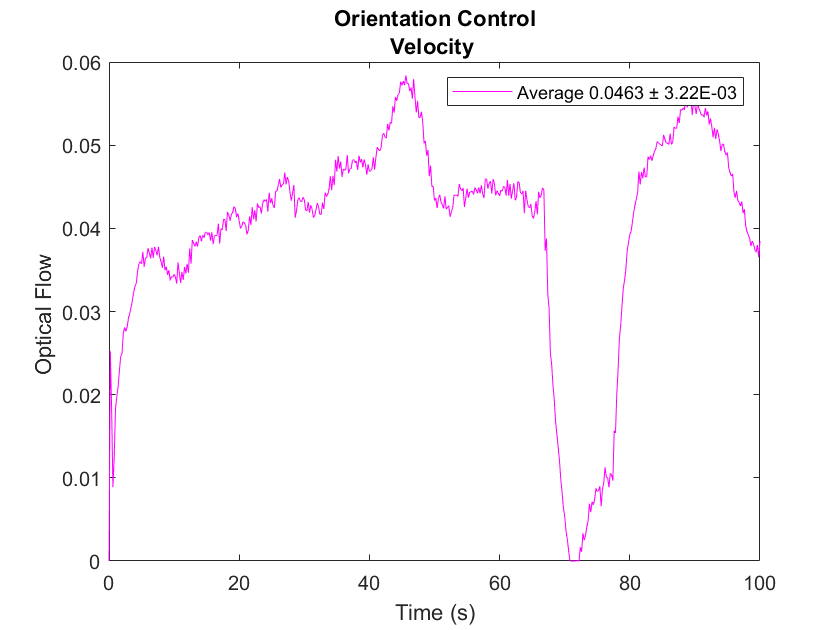


f = plot(x,y,'m');
xlabel('Time (s)');
ylabel('Optical Flow ');
title({'Orientation Control' ; 'Velocity '})
legend({speed},'Location','northeast')